## Nominel Levetid (Lejeopgave 1)

### Opgave

Gokartaksel med en diameter på $D = 25 mm$ og $d = 0.6D$ roterer med en hastighed på $2900 r/min$.

Den er ophængt i to SKF single row deep groove ball bearings. Beregn den nominelle levetid i henhold til ISO for begge lejer, se diagram. 

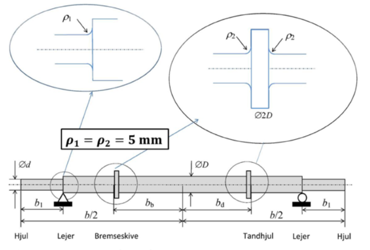


$$b_1 = 100 mm \qquad b_d = b_b = 100 mm \qquad b = 1000 mm$$


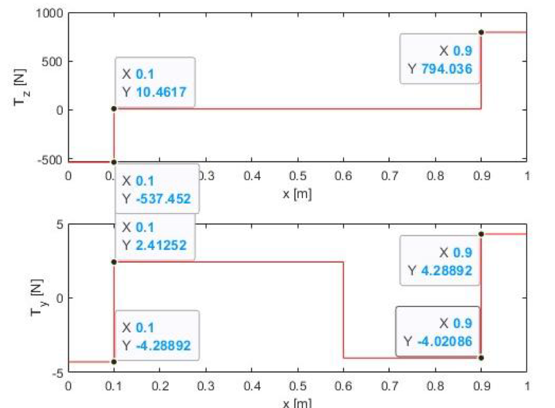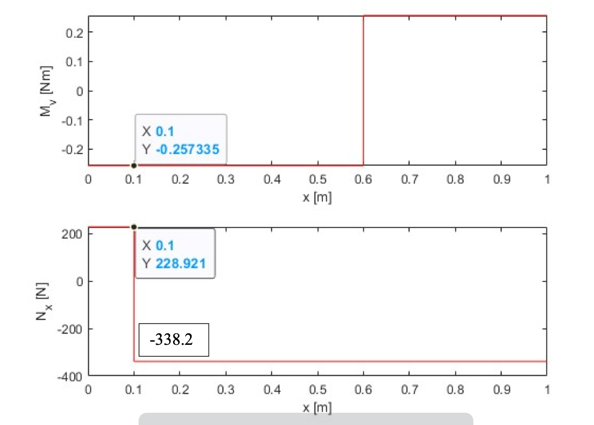

**Venstre leje**

Ved aflæsning har vi:

F_a = 228.921 - (-338.2);
F_rz = 10.4617 - (-537.452);
F_ry = 2.41252 - (-4.28892);
F_r = sqrt(F_ry^2 + F_rz^2);

Vi vælger det mindste leje med den påkrævede diameter (61805-2RS1)

C = 4.36e3;
C0 = 2.6e3;
f0 = 14;

Vi regner nu $\frac{\;f_0 F_a }{C_0 }$:

beregningsfaktor = f0 * F_a/C0;
fprintf("Den påkrævede værdi af f0 * F_a/C0 er %.2f", beregningsfaktor);

Den påkrævede værdi af f0 * F_a/C0 er 3.05

Ved aflæsning i Table 9 har vi at $0.34 \leq e \leq 0.38$.

Vi skal nu tjekke om $\frac{F_a }{F_r }$ er større eller mindre end $e$.

kraftforhold = F_a/F_r;
fprintf("Kraftforholdet er %.2f", kraftforhold);

Kraftforholdet er 1.03

Eftersom $\frac{F_a }{F_r }\ge e$ => $P=X\;F_r +{\mathrm{YF}}_a$. Fra tabel 9 har vi:

X = 0.56;
Y = 1.31 + (1.15 - 1.31)/((3.45 - 2.07) * (3.06 - 2.07));

P = X * F_r + Y * F_a;
fprintf("Altså er P = %.2f N", P);

Altså er P = 983.37 N


%Livstid
n = 3;
L10 = (C/P)^n;
fprintf("Altså holder lejet i %.3f millioner omdrejninger", L10);

Altså holder lejet i 87.159 millioner omdrejninger

**Højre leje**

%Aflæste størrelser
F_ah = 0;
F_rzh = 794.036 - 10.462;
F_ryh = 4.28892 - (-4.02086);
F_rh = sqrt(F_rzh^2 + F_ryh^2);

kraftforhold_h = F_ah/F_rh;
fprintf("Kraftforholdet er %.2f", kraftforhold_h);

Kraftforholdet er 0.00

Dette er mindre end $e$ hvilket giver:

Ph = F_rh;

%Livstid
L10h = (C/Ph)^n;
fprintf("Altså holder lejet i %.3f millioner omdrejninger", L10h);

Altså holder lejet i 172.245 millioner omdrejninger